# FNN CNN LSTM - 출력값 = 유저패턴 

change

BatteryNum = 

_05_v2  => *05_*v2

Prediciton #56 by model

%clear

## 저장된 데이타를 모두 읽어들인다.

%{
load data_05 
load data_06 
load data_07 
load data_0506 
load data_0606 
load data_05plus06      
load data_05plus07      
load data_06plus07      
load data_05plus06plus07
%}

load cap_05             
load cap_06             
load cap_07             
load cap_0506           
load cap_0605           
load cap_05plus06       
load cap_05plus07       
load cap_06plus07       
load cap_05plus06plus07 

load charVIT_05
load charVIT_06
load charVIT_07
load charVIT_0506              
load charVIT_0605              
load charVIT_05plus06          
load charVIT_05plus07          
load charVIT_06plus07          
load charVIT_05plus06plus07    

load InitC_05 				
load InitC_06 				
load InitC_07 				
load InitC_0506 			
load InitC_0605 			
load InitC_05plus06 		
load InitC_05plus07 		
load InitC_06plus07 		
load InitC_05plus06plus07 	

load charVIT_input_size                  
load charVIT_05plus06_input_size         
load charVIT_05plus07_input_size         
load charVIT_06plus07_input_size         
load charVIT_05plus06plus07_input_size  

% ryan 
load yCap_05                 yPattern_05                   x_05                                                                             
load yCap_06                 yPattern_06                   x_06                                                                             
load yCap_07                 yPattern_07                   x_07                                                                             
load yCap_0506               yPattern_0506                 x_0506                                                                           
load yCap_0605               yPattern_0605                 x_0605                                                                           
load yCap_05plus06           yPattern_05plus06             x_05plus06                                                                       
load yCap_05plus07           yPattern_05plus07             x_05plus07                                                                       
load yCap_06plus07           yPattern_06plus07             x_06plus07                                                                                  
load yCap_05plus06plus07     yPattern_05plus06plus07       x_05plus06plus07   

load cap_all_max  cap_all_min  cap_all_rate 
load pattern_all_max  pattern_all_min  pattern_all_rate 

% ryan -- remove 
% y_05plus06plus07_pattern => yPattern_05plus06plus07
% ym_05plus06plus07_pattern  => pattern_all_min
% yr_05plus06plus07_pattern => pattern_all_rate



% ryan xB_ => x_   yB_ => yCap_
% yr_05 => cap_all_rate 
% ym_05 => cap_all_min 
BatteryNum = 65 ;
yr = cap_all_rate;
ym = cap_all_min;

switch BatteryNum
    case 5
        Train_Input = x_05;
        Train_Output = yCap_05;
    case 6
        Train_Input = x_06;
        Train_Output = yCap_06;
    case 7
        Train_Input = x_07;
        Train_Output = yCap_07;
    case 56
        Train_Input = x_0506;
        Train_Output = yCap_0506;
    case 65
        Train_Input = x_0605;
        Train_Output = yCap_0605;
    case 562
        Train_Input = x_05plus06;
        Train_Output = yCap_05plus06;
    case 572
        Train_Input = x_05plus07;
        Train_Output = yCap_05plus07;
    case 672
        Train_Input = x_06plus07;
        Train_Output = yCap_06plus07;
    case 5673
        Train_Input = x_05plus06plus07;
        Train_Output = yCap_05plus06plus07;
    case 56731
        Train_Input = x_05plus06plus07;
        Train_Output = yPattern_05plus06plus07;
        yr = pattern_all_rate;
        ym = pattern_all_min;         
end

BatteryNum

BatteryNum = 5

yr

yr = 1.7640

ym

ym = 1.1538

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.25 |         0.27 |       0.0314 |       0.0358 |          0.0010 |
|      50 |          50 |       00:00:04 |         0.07 |         0.08 |       0.0026 |       0.0035 |          0.0010 |
|     100 |         100 |       00:00:05 |         0.02 |         0.03 |       0.0002 |       0.0005 |          0.0010 |
|     150 |         150 |       00:00:06 |         0.02 |         0.02 |       0.0001 |   

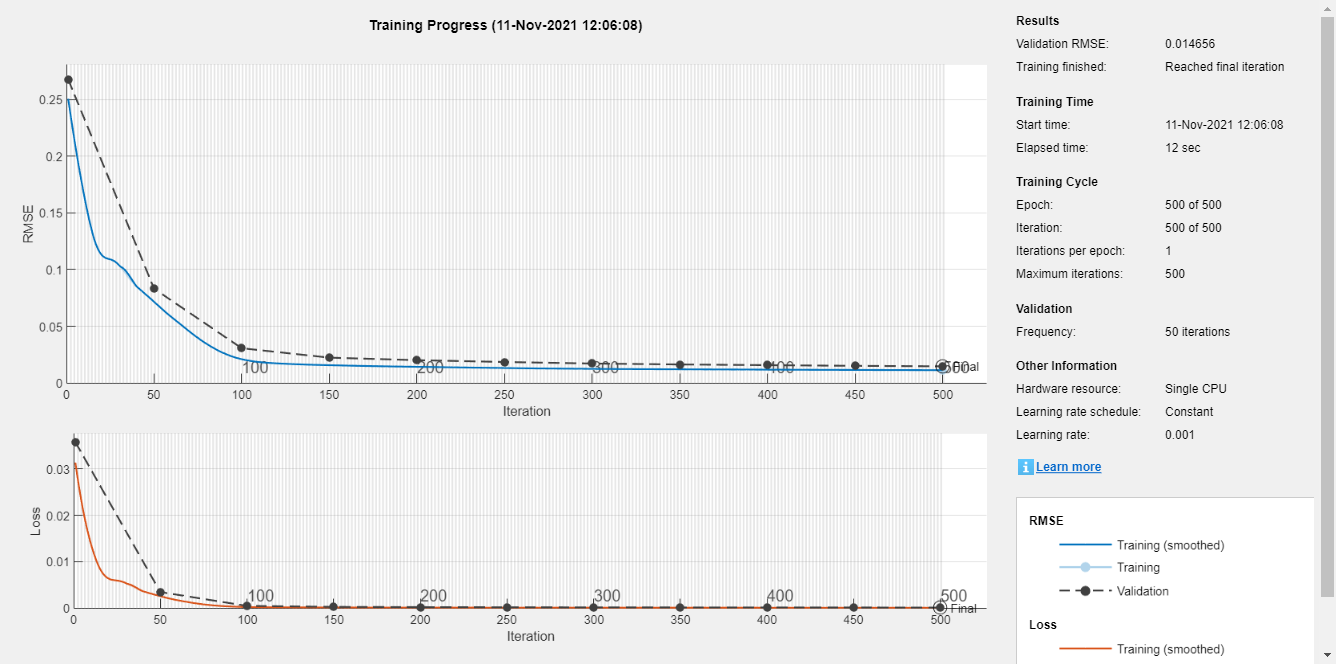

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.27 |         0.29 |       0.0359 |       0.0429 |          0.0010 |
|      50 |          50 |       00:00:05 |         0.05 |         0.06 |       0.0015 |       0.0017 |          0.0010 |
|     100 |         100 |       00:00:06 |         0.02 |         0.02 |       0.0002 |       0.0002 |          0.0010 |
|     150 |         150 |       00:00:07 |         0.02 |         0.02 |       0.0002 |   

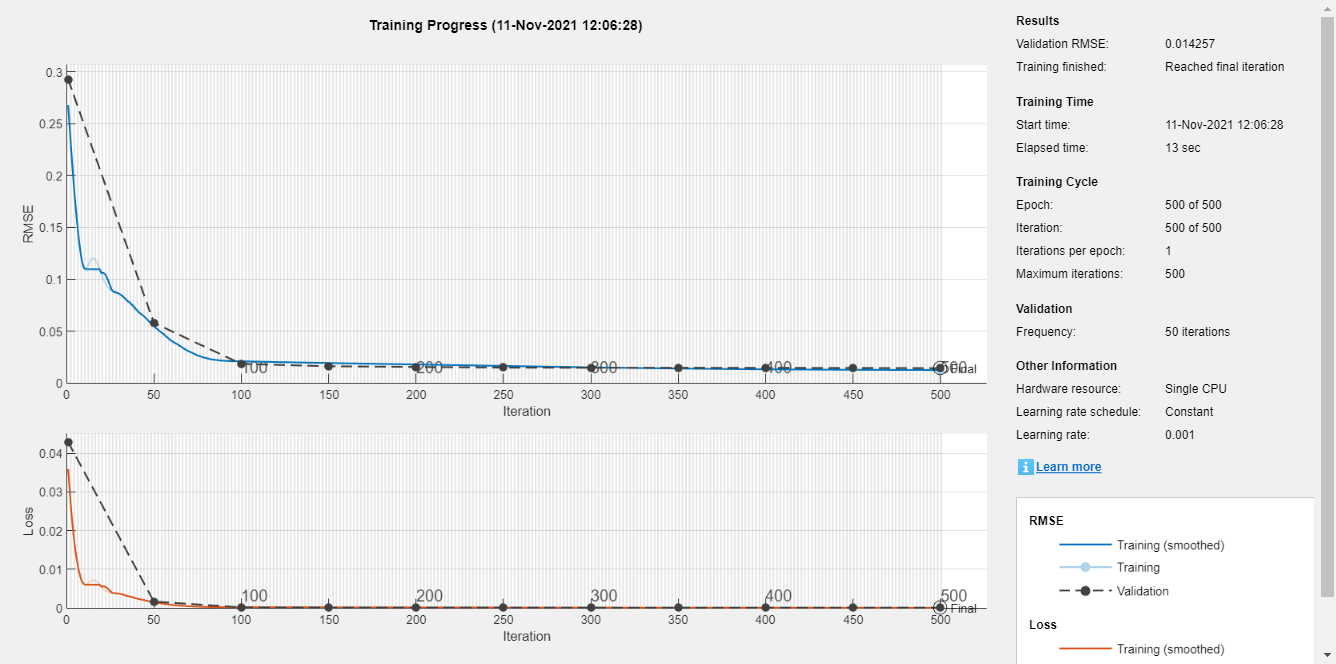

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.34 |         0.33 |       0.0575 |       0.0560 |          0.0010 |
|      50 |          50 |       00:00:07 |         0.07 |         0.07 |       0.0024 |       0.0023 |          0.0010 |
|     100 |         100 |       00:00:08 |         0.04 |         0.05 |       0.0010 |       0.0011 |          0.0010 |
|     150 |         150 |       00:00:09 |         0.03 |         0.03 |       0.0004 |       0.0004 |          0.0010 |
|     20

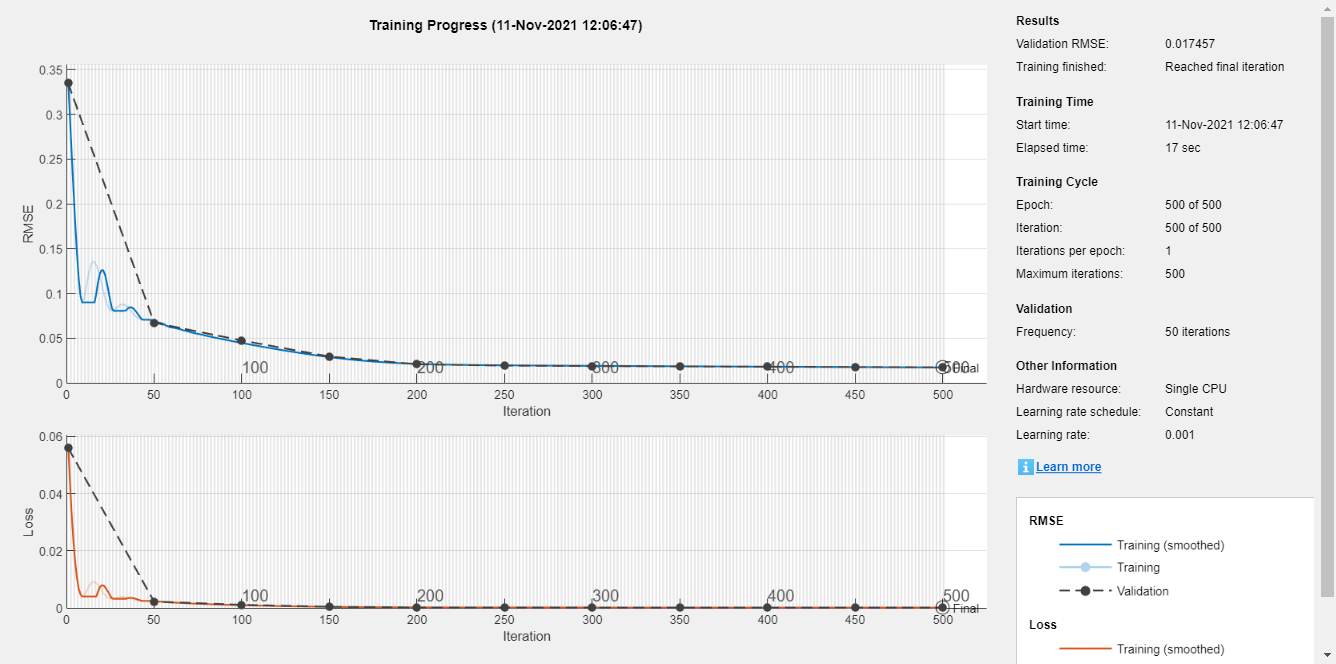

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_0605_v2 = netFNN40;
netCNN1_0605_v2 = netCNN1;
netCNN2_0605_v2 = netCNN2;
netLSTM_0605_v2 = netLSTM;
netGRU_0605_v2 = netGRU;

save  netFNN40_0605_v2
save  netCNN1_0605_v2
save  netCNN2_0605_v2
save  netLSTM_0605_v2
save  netGRU_0605_v2


### Prediciton using each 5 trained model

Make a prediction using trained models

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, charVIT_05plus06plus07_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

- GRU : 1 gru layer with 100 hidden units

pGRU = cell2mat(predict(netGRU, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*yr + ym;
pFNN40 = pFNN40*yr + ym;
pCNN1 = pCNN1*yr + ym;
pCNN2 = pCNN2*yr + ym;
pLSTM = pLSTM*yr + ym;
pGRU = pGRU*yr + ym;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.'),plot(pGRU, '*--'),
plot(1:60, 1.4*ones(1, 60),'k--','LineWidth', 2), xlim([1 60])
title(['Capacity Estimation using V, I, T (Battery #', '5+6+7', ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

RMSE

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))
rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))
rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))
rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))
rmse_pGRU = sqrt(mean(( Train_Output' - pGRU' ).^2))

### Prediciton #56 by model #65. 

load  netFNN40_0605_v2 
load  netCNN1_0605_v2 
load  netCNN2_0605_v2 
load  netLSTM_0605_v2 
load  netGRU_0605_v2 


BatteryNum = 56;
pFNN40_0506 = netFNN40_0605_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_0605_v2, x_4d);
pCNN2_0506 = predict(netCNN2_0605_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_0605_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_0605_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *yr + ym ;
pFNN40_0506 = pFNN40_0506 *yr + ym ;
pCNN1_0506 = pCNN1_0506 *yr + ym ;
pCNN2_0506 = pCNN2_0506 *yr + ym ;
pLSTM_0506 = pLSTM_0506 *yr + ym ;
pGRU_0506 = pGRU_0506 *yr + ym ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')


rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506)) - pFNN40_0506').^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

[1] B. Saha and K. Goebel, ``Battery data set,''NASA AMES Prognostics Data Repository, 2007.

[2] Choi, Yohwan, et al. "Machine Learning-Based Lithium-Ion Battery Capacity Estimation Exploiting Multi-Channel Charging Profiles." *IEEE Access* 7 (2019): 75143-75152.

***Copyright 2019 The MathWorks, Inc.***